# Digital Signal Processing -- Homework 5

#### Moving Average and Windowed SINC Filters

# Problem 1 -- Moving Average Filters

In MATLAB create an impulse response for a moving average filter with a kernel of length.  Plot the frequency response of the filter using the freqz function.  Apply the filter to the data in the MATLAB data file XX.mat.  Now create an impulse response of a MAV filter that is XX in filter length.  Plot the frequency response of the filter.  Apply this filter to the data from the MATLAB file.

Create an impulse response for a Moving average filter of length 31. Recall that the impulse response for a Moving average filter is a kernal with all the same values where the value is one over the length of the  filter. For example: hMAV = [1/N, 1/N, 1/N, 1/N,...... 1/N];  where N is the length of the filter.

Hint:  One easy way to create a vector of all the same values in MATLAB  is to use the "ones(N,M)" function.  This creates a matrix of size N by M of all ones.  You can use "ones(1,N) to create a row vector of all  ones.  Then you can scale the vector by the magnitude of the value that you want for all the elements.  That is if I want a vector of length 20 where all the values are 3 I would use x = ones(1,20) * 3;

Here is an example of creating a length 11 moving average filter in MATLAB

## MAV Filter Example

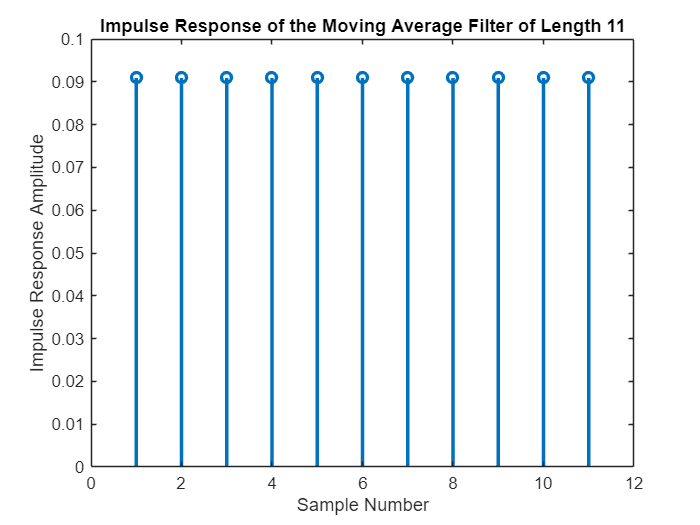

% Example

filterLength = 11;
hMAV11 = ones(1,filterLength) * (1/filterLength);

%  Plot the impulse response. Use the STEM function to plot the individual
%  values of the response

figure
stem( hMAV11, 'LineWidth',2 )
title('Impulse Response of the Moving Average Filter of Length 11');
xlabel('Sample Number');
ylabel('Impulse Response Amplitude')

## Plot the Frequency Response of a Digital Filter

Plot the frequency response of the filter.  Use the freqz function.

The freqz function is in the form of: [h,w] = freqz( b, a, numFreqSamples )

where b is the numerator and a is  the denominator of the z-transform of the filter.  In the case of an  FIR filter, the denominator a is just 1 and numerator is the impulse response of the filter hMAV.  


$$H(z) = \frac{h[0] + h[1]z^{-1}+h[2]z^{-2}+...+h[N-1]z^{n-1}}{1}
$$


The number of samples is the number of  samples in the frequency domain. The output value h is a vector of the complex value of the frequency response.  The vector w is a vector of the frequency points corresponding to the points in the frequency response. The frequency values represent the points around the circle in the z-domain from angle 0 to pi.

See <help freqz> in MATLAB for more (and better) information

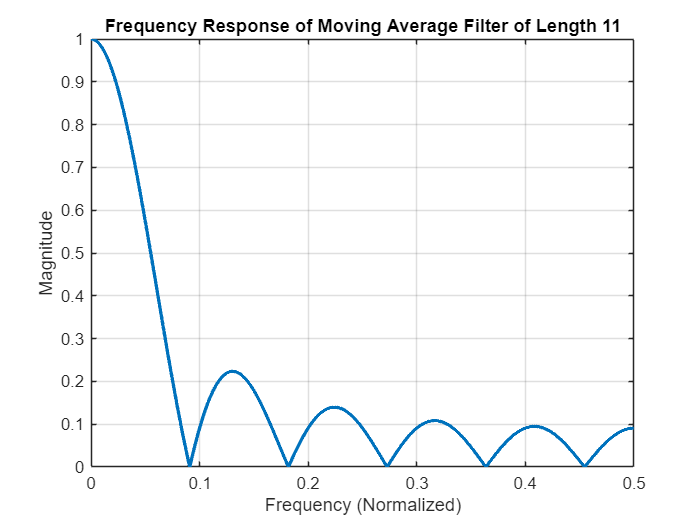

%  Compute the frequency response of the filter
nSamples = 2048;
[h,w] = freqz(hMAV11, 1, nSamples);

figure
plot(w/(2*pi), abs(h),'LineWidth',2 );
grid on
title('Frequency Response of Moving Average Filter of Length 11')
xlabel('Frequency (Normalized)');
ylabel('Magnitude')

## Create a length 31 Moving Average Filter

Now create your own impulse response of the moving average filter for a length of 31.  Be sure to create a new variable name for the impulse response to keep it separate from the length 11 MAV impulse response. You'll use both again.  Plot the impulse response and the frequency response of the filter. Use appropriate titles and axes labels

MAV Filter Equation:


$$y[i] = \frac{1}{M}\sum_{j=0}^{M-1} {x[i+j]$$


% MAV kernel length
M31 = 31;

MAV Filter Kernel for Convolution:


$$h[n] = [\frac{1}{M},\frac{1}{M},\frac{1}{M},...,\frac{1}{M}]$$


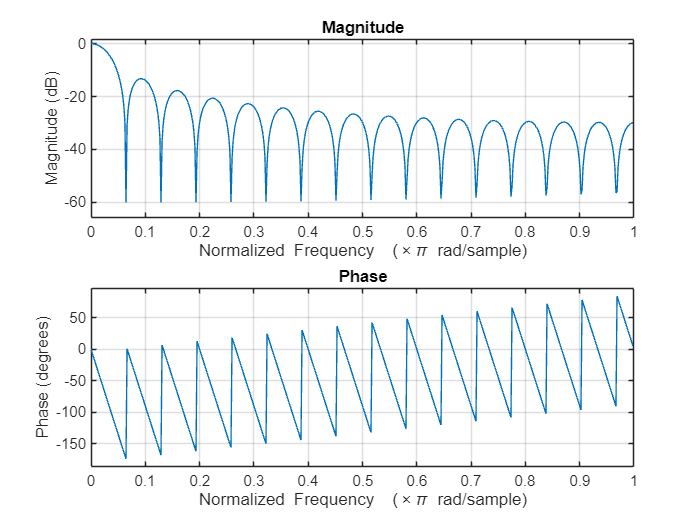

% MAV kernel
hMAV31 = ones(1,M31) * (1 / M31);

% Plot frequency response and impulse response of MAV kernel
freqz(hMAV31)

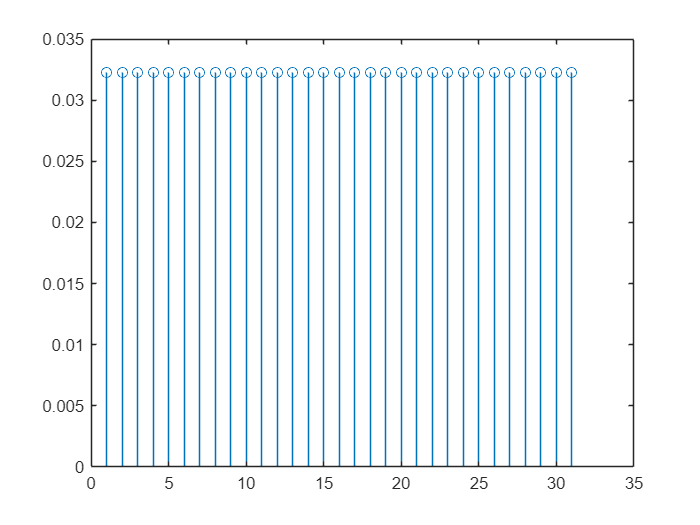

stem(hMAV31)

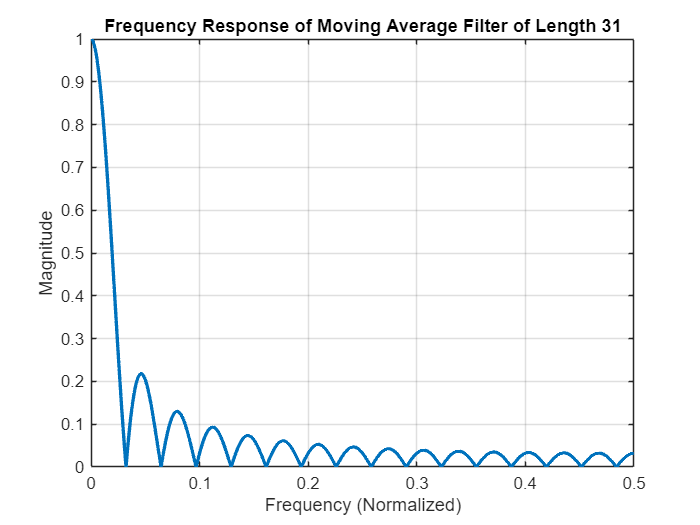

%  Compute the frequency response.  Be sure to create a new variable for
%  the frequency response and the frequency vector as you'll use these
%  again.
[freqResponse31,freqVector31] = freqz(hMAV31, 1, nSamples);

% Plot frequency response
figure
plot(freqVector31/(2*pi), abs(freqResponse31),'LineWidth',2 );
grid on
title('Frequency Response of Moving Average Filter of Length 31')
xlabel('Frequency (Normalized)');
ylabel('Magnitude')

## Create a length 101 Moving Average Filter

Now create a Moving Average filter with impulse response of length 101. Be sure to name it differently than the filter of length 31 as you will use them both again. Compute the frequency response of the filter.  Again use a new variable name for both the frequency response and the frequency.  Plot the frequency response of both the length 31 and length 101 moving average filters.

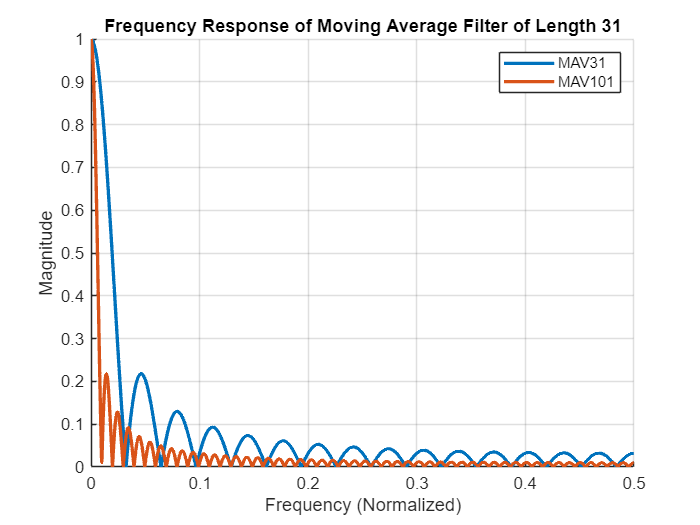

%   Moving Average filter of length 101.  Plot both frequency responses on
%   the same graph

% MAV kernel length
M101 = 101;

% MAV kernel
hMAV101 = ones(1,M101) * (1 / M101);

%  Compute and plot the frequency response
[freqResponse101,freqVector101] = freqz(hMAV101, 1, nSamples);

figure
hold on
plot(freqVector31/(2*pi), abs(freqResponse31),'LineWidth',2 );
plot(freqVector101/(2*pi), abs(freqResponse101),'LineWidth',2 );
grid on
legend('MAV31','MAV101')
title('Frequency Response of Moving Average Filter of Length 31')
xlabel('Frequency (Normalized)');
ylabel('Magnitude');
hold off

# Problem 2 -- Apply the MAV filter to an input signal

The moving average filter is an FIR filter.  We will implement the filter using convolution.  MATLAB has a function to perform convolution. It is "w = conv( u, v )".  Use the MATLAB help function to better learn how to use the convolution function. The input arguments u and v are  the input sequences to the function.  Since convolution is commutative you can put them in either order. The output is the variable w.  The variable w includes the end effects, so you will want to remove the end effects of the result.

Load the input signal file "HW_05_Problem_2_Signal.mat".  Convolve the input sequence from the file with the impulse response of each of the three impulse responses.  Plot the individual responses then plot all three moving average filter and plot the outputs on the same graph.  Comment on the difference between the three filters below.

1.

% Load the file "HW_05_Problem_2_Signal.mat".  This will load two variables into the workspace.
% One "sample" is the sample number.
% The other is "signal" and is the signal of interest.
% 
%  Convolve the input signal from the file "HW_05_Problem_2_Signal.mat"
%  with the moving average filter of length 31 and 101. The variable loaded into the workspace
%  is called "signal".

% clear workspace variables except for those carried over
clearvars -except hMAV11 hMAV31 hMAV101

%  load the file "HW_05_Problem_2_Signal.mat" into the workspace
fileName = 'HW_05_Problem_2_Signal.mat';
load(fileName);

Input Side Convolution Function (written by me)

% % Function that performs input side convolution on a signal with an impulse
% % response
% function yOut = Convolve(input, impulse)
% 
%     %  Find the length of the input sequence and the impulse response
%     inputLength = length(input);  % Length of the input sequence
%     impulseLength= length(impulse);  % Length of the impulse response
% 
%     % Length of the output sequence is length of input plus length of
%     % impulse minus 1
%     convLength = inputLength + impulseLength - 1;
% 
%     %  Initialize the output sequence to all zeros
%     yOut = zeros(1,convLength);
% 
%     % Decompose input signal into individual impulses
%     inputDecomp = zeros(inputLength,1);  % initialize vertical array
%     for i = 1:inputLength
%         inputDecomp(i,1) = input(1,i);
%     end
% 
% 
% 
% end

Output Side Convolution Function from Matlab Grader Assignment 2

function yOut = Convolution( inputX, impulseH )

%  The Convolution function convolves the input sequence 'inputX' and the
%  system impulse response 'impulseH' to result in the output value yOut.
%
%  The output of the convolution is the sequence yOut.  If the inputX has a
%  length of M and the impulseH has a length of N, then the output sequency
%  yOut has a length of M+N-1
%
%
%  Input Arguments
%
%  inputX -- input sequence of length M
%  impulseH -- impulse response of length N
%
%  yOut -- result of the convolution of length M+N-1

%  Find the length of the input sequence and the impulse response
M = length(inputX);    % Length of the first input argument inputX
N = length(impulseH);  % Length of the second input argument impulseH

%  Compute the length of the output sequence is M+N-1
convLength = M + N - 1;

%  Initialize the output sequence to all zeros
yOut = zeros(1,convLength);

%  Implement the convolution routine
    for i = 1:convLength  % iterate over the output signal

        % -------------- Kernel -------------- %
        for j = 1:N  % iterate over the impulse response (kernel)

            if (i-j + 1) < 1  % make sure an array index of less than 1 is not passed to inputX
                continue
            elseif (i-j + 1) > M  % i still dont know what this does
                continue
            else
                yOut(i) = yOut(i) + impulseH(j) * inputX(i-j + 1);  % multiply input by impulse response and sum each multiple moving from right to left
            end
           
        end
        % ------------------------------------ %
        
    end

end

2.

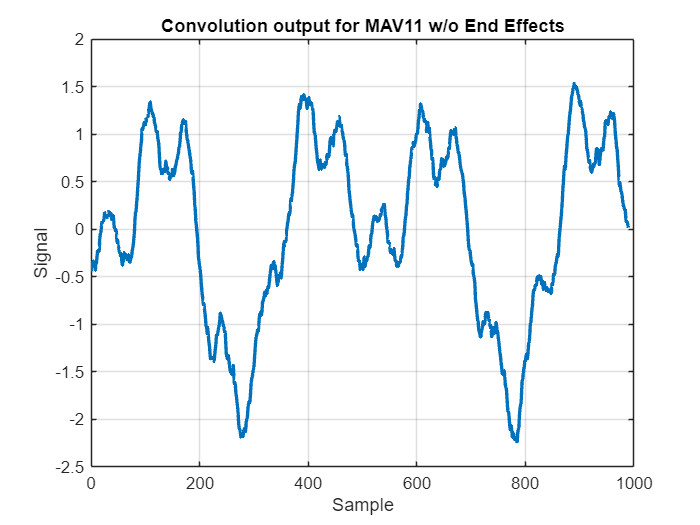

%  Convolve the input signal with the length 11 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 10 samples on the beginning and at the end

% Calculate end effects
endEffects = length(hMAV11) - 1;

% Perform convolution
convMAV11 = Convolution(signal, hMAV11);

% Remove end effects from beginning
convMAV11(1:endEffects) = [];

% Remove end effects from end
flip(convMAV11);
convMAV11(1:endEffects) = [];
flip(convMAV11);

% Plot the convolution output with end effects removed
figure
plot(convMAV11,'LineWidth',2)
grid on
title('Convolution output for MAV11 w/o End Effects')
xlabel('Sample')
ylabel('Signal')

3.

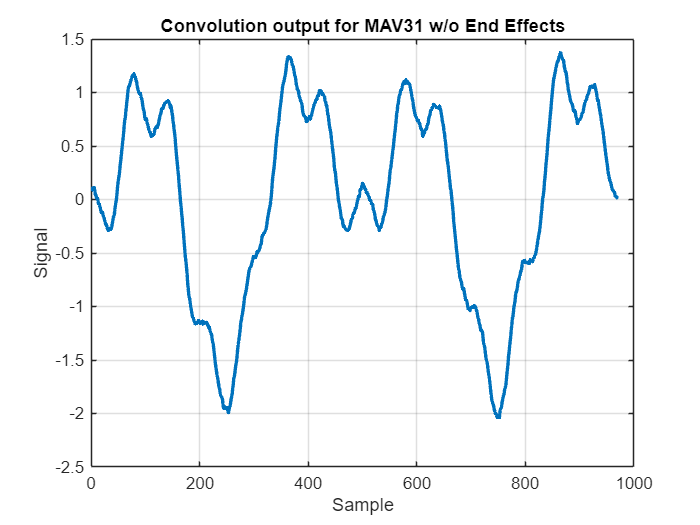

%  Convolve the input signal with the length 31 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 30 samples on the beginning and at the end

% Calculate end effects
endEffects = length(hMAV31) - 1;

% Perform convolution
convMAV31 = Convolution(signal, hMAV31);

% Remove end effects from beginning
convMAV31(1:endEffects) = [];

% Remove end effects from end
flip(convMAV31);
convMAV31(1:endEffects) = [];
flip(convMAV31);

% Plot the convolution output with end effects removed
figure
plot(convMAV31,'LineWidth',2)
grid on
title('Convolution output for MAV31 w/o End Effects')
xlabel('Sample')
ylabel('Signal')

4.

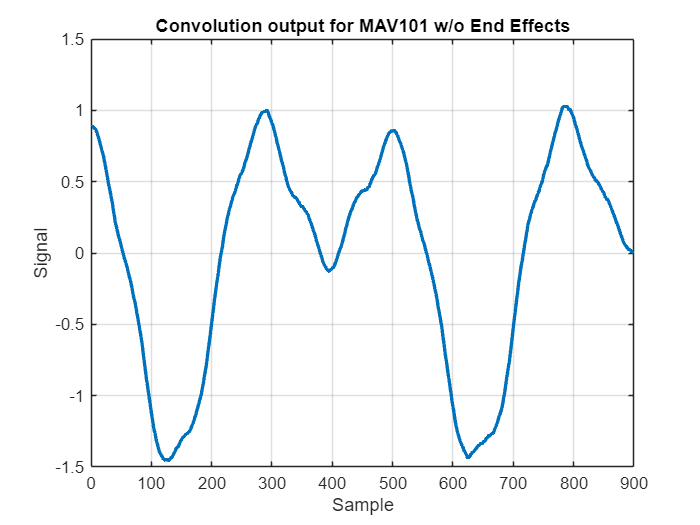

%  Convolve the input signal with the length 101 MAV filter impulse response
%  filter.  Plot the output of the convolution.
%
%  Remove the end effects.  M-1 = 100 samples on the beginning and at the end

% Calculate end effects
endEffects = length(hMAV101) - 1;

% Perform convolution
convMAV101 = Convolution(signal, hMAV101);

% Remove end effects from beginning
convMAV101(1:endEffects) = [];

% Remove end effects from end
flip(convMAV101);
convMAV101(1:endEffects) = [];
flip(convMAV101);

% Plot the convolution output with end effects removed
figure
plot(convMAV101,'LineWidth',2)
grid on
title('Convolution output for MAV101 w/o End Effects')
xlabel('Sample')
ylabel('Signal')

5.

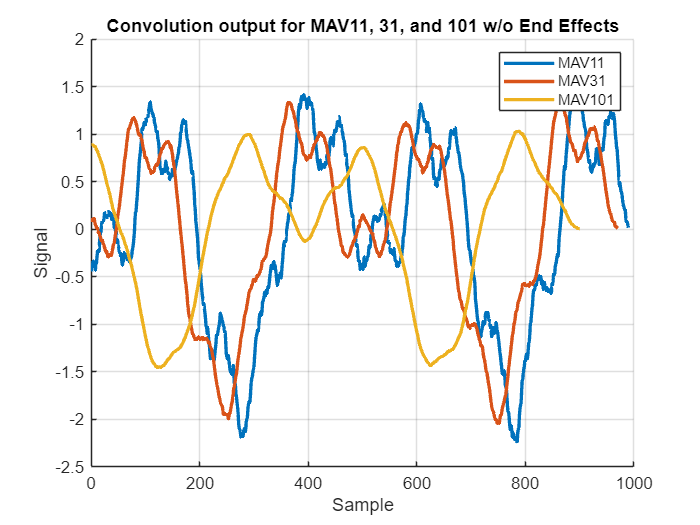

%  Plot all three convolution outputs with end effect removed on the same
%  graph below
figure
hold on
plot(convMAV11,'LineWidth',2)
plot(convMAV31,'LineWidth',2)
plot(convMAV101,'LineWidth',2)
legend('MAV11','MAV31','MAV101')
grid on
title('Convolution output for MAV11, 31, and 101 w/o End Effects');
xlabel('Sample');
ylabel('Signal');
hold off

## Questions

#### Which filter removed the noise the best without distorting the output.  Did any of the filters distort the output?  Why?

MAV31 was the best to remove the noise without distorting the output. MAV101 overaveraged the input to the point of losing data.

# Problem 3 -- Windowed SINC Low Pass Filter

A)  I've done this first part for you as an example.  Using the FIR_Designer tool, I created a  truncated SINC lowpass filter with no window ('Window' parameter set to 'none') with a cut off frequency of 70 BPM assuming a sampling rate of 600 BPM.  I used a filter kernel length of 201. I plotted the impulse and the  frequency responses of the filter in decibels.. 

## Plot the impulse response -- Example

freqCornerLPF = 70;
filterLength = 201;

hLPF = FIR_Designer( 'nOrder', filterLength, 'cutBPM', freqCornerLPF, 'Window','none', 'PrintHeader',false,'PlotResponses',false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 4096;

h = [-11, -4, 5, 12, 13, 7, -3, -11, -14, -10, 0, 10, 15, 12,...
3, -8, -15, -14, -6, 5, 14, 16, 10, -2, -13, -17, -13, -2,...
11, 18, 16, 6, -8, -18, -19, -10, 4, 17, 21, 14, 0, -15,...
-22, -18, -5, 12, 23, 22, 10, -8, -23, -26, -16, 3, 21, 29,...
22, 3, -18, -31, -28, -10, 14, 32, 34, 19, -8, -32, -40, -28,...
0, 30, 46, 39, 10, -26, -52, -52, -24, 19, 56, 67, 43, -8,...
-60, -87, -69, -10, 64, 116, 113, 45, -66, -170, -206, -130, 68, 351,...
647, 871, 954, 871, 647, 351, 68, -130, -206, -170, -66, 45, 113, 116,...
64, -10, -69, -87, -60, -8, 43, 67, 56, 19, -24, -52, -52, -26,...
10, 39, 46, 30, 0, -28, -40, -32, -8, 19, 34, 32, 14, -10,...
-28, -31, -18, 3, 22, 29, 21, 3, -16, -26, -23, -8, 10, 22,...
23, 12, -5, -18, -22, -15, 0, 14, 21, 17, 4, -10, -19, -18,...
-8, 6, 16, 18, 11, -2, -13, -17, -13, -2, 10, 16, 14, 5,...
-6, -14, -15, -8, 3, 12, 15, 10, 0, -10, -14, -11, -3, 7,...
13, 12, 5, -

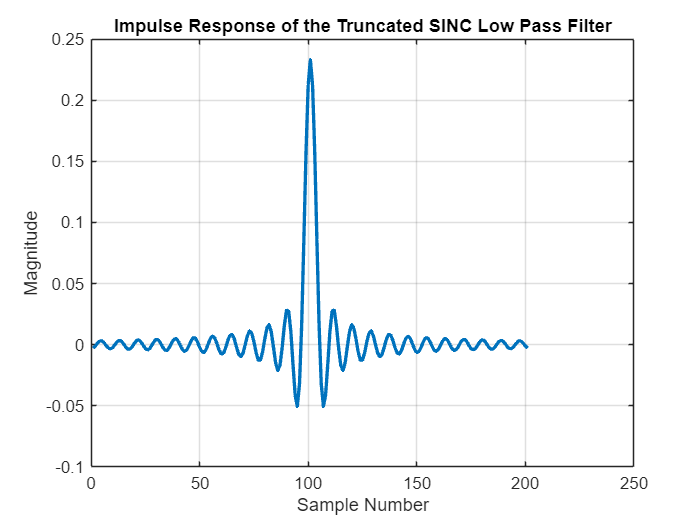

%  Plot the impulse response.

figure
plot(hLPF,'LineWidth',2)
grid on
title('Impulse Response of the Truncated SINC Low Pass Filter')
xlabel('Sample Number')
ylabel('Magnitude')

## Plot the frequency response -- Example

Plot the decibal magnitude of the response versus the frequency in  breaths per minute.  Use 20*log10( abs( fResponseTruncatedSINC) ).  The frequency response output is complex so find the magnitude using abs().  Plot in decibels using 20*log10( x ) where x is the magnitude of the frequency response.

The freqz function creates a vector of frequencies from 0 to pi (the Nyquist frequency).  Convert that to a vector of frequencies from 0 to 300 BPM.  300 BPM is the Nyquist frequency when sampling at 600 bpm.  Do this by dividing the frequency vector by $2\pi$ then multiplying by 600 bpm the sample rate.

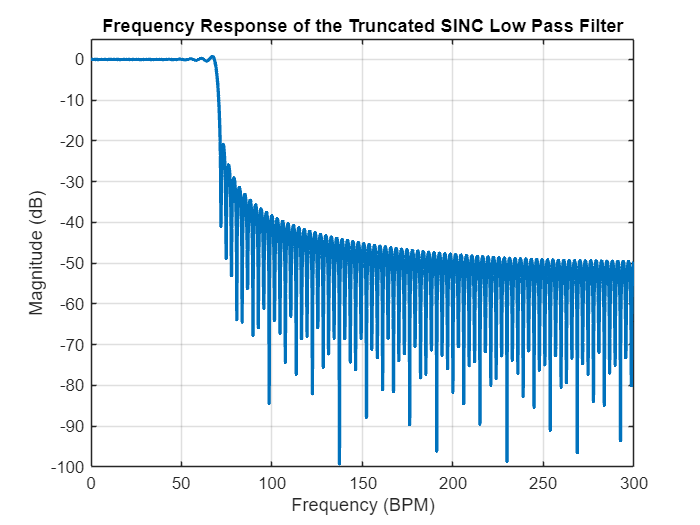

%  Plot the frequency response using the freqz function.
nSamples = 2048;  %  Use 2048 samples in the frequency response
[fResponseTruncatedSINC, wTruncatedSINC ] = freqz( hLPF, 1,  nSamples );


figure
plot(wTruncatedSINC/(2*pi)*600, 20*log10(abs(fResponseTruncatedSINC)),'LineWidth',2);
grid on
title('Frequency Response of the Truncated SINC Low Pass Filter')
xlabel('Frequency (BPM)')
ylabel('Magnitude (dB)')
xlim([0,300])
ylim([-100,5])

## Questions

#### What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How much attenuation is achieved in the stop band of the filter?

The passband is not flat, there is a growing ripple as the signal approaches the cutoff frequency.

B)  Now, your turn.  Create the same filter using a Hamming window and compare the frequency responses.  Modify the parameters of the FIR_Designer command appropriately.

## Create a Windowed SINC filter using a Hamming Window

Use the FIR_Designer function and use a Hamming window by changing the 'Window' parameter to the value 'Hamming'.

%  Create a windowed SINC low pass filter using a Hamming window
hamLPF = FIR_Designer( 'nOrder', filterLength, 'cutBPM', freqCornerLPF, 'Window','Hamming', 'PrintHeader',false,'PlotResponses',false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 4096;

h = [-1, 0, 0, 1, 1, 1, 0, -1, -1, -1, 0, 1, 2, 1,...
0, -1, -2, -2, -1, 1, 2, 3, 2, 0, -3, -4, -3, 0,...
3, 5, 4, 2, -2, -5, -6, -3, 1, 6, 8, 5, 0, -6,...
-10, -8, -2, 6, 11, 11, 5, -4, -12, -14, -9, 2, 13, 18,...
14, 2, -12, -21, -19, -7, 10, 23, 25, 14, -6, -25, -32, -22,...
0, 25, 39, 33, 9, -23, -45, -46, -22, 17, 51, 62, 40, -8,...
-57, -83, -66, -10, 62, 113, 110, 44, -65, -168, -205, -130, 68, 351,...
648, 872, 956, 872, 648, 351, 68, -130, -205, -168, -65, 44, 110, 113,...
62, -10, -66, -83, -57, -8, 40, 62, 51, 17, -22, -46, -45, -23,...
9, 33, 39, 25, 0, -22, -32, -25, -6, 14, 25, 23, 10, -7,...
-19, -21, -12, 2, 14, 18, 13, 2, -9, -14, -12, -4, 5, 11,...
11, 6, -2, -8, -10, -6, 0, 5, 8, 6, 1, -3, -6, -5,...
-2, 2, 4, 5, 3, 0, -3, -4, -3, 0, 2, 3, 2, 1,...
-1, -2, -2, -1, 0, 1, 2, 1, 0, -1, -1, -1, 0, 1,...
1, 1, 0, 0, -1];


Plot the impulse response and the frequency response as in the example.  Create a separate variable for the Hamming window impulse response results as well as the frequency response results.

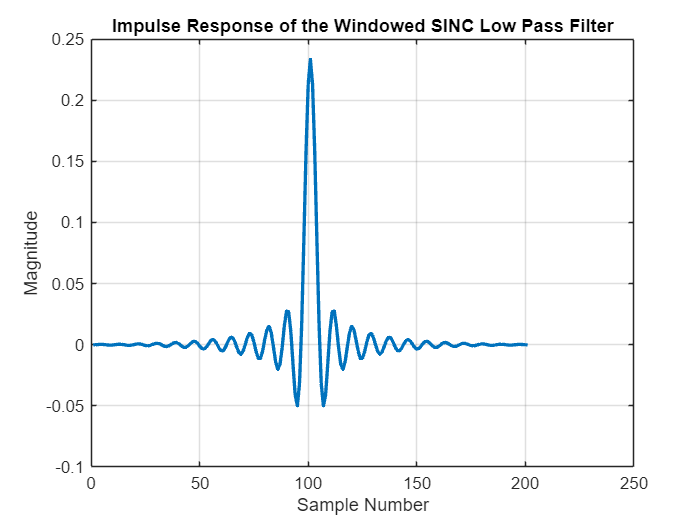

%  Plot the impulse response.
figure
plot(hamLPF,'LineWidth',2)
grid on
title('Impulse Response of the Windowed SINC Low Pass Filter')
xlabel('Sample Number')
ylabel('Magnitude')

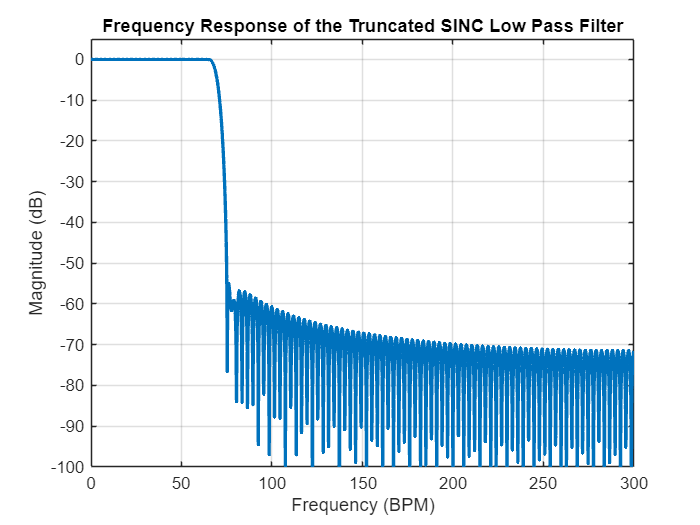


%  Plot the frequency response using the freqz function.
nSamples = 2048;  %  Use 2048 samples in the frequency response
[fResponseTruncatedSINC, wTruncatedSINC ] = freqz( hamLPF, 1,  nSamples );

figure
plot(wTruncatedSINC/(2*pi)*600, 20*log10(abs(fResponseTruncatedSINC)),'LineWidth',2);
grid on
title('Frequency Response of the Truncated SINC Low Pass Filter')
xlabel('Frequency (BPM)')
ylabel('Magnitude (dB)')
xlim([0,300])
ylim([-100,5])

## Questions

**What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How does it compare to the truncated SINC filter?  How much attenuation is achieved in the stop band of the filter?  How does it compare to the truncated SINC filter?**

# Problem 4 -- Windowed SINC High Pass Filter

A)  Using the FIR_Designer tool, now create a truncated SINC **highpass** filter ('Window' value of 'none') with a cut off frequency of 40 BPM assuming a sampling rate of 600 BPM.  Use a filter length of 201.  Plot the impulse response and the frequency response of the filter in decibels..

B)  Then create the same filter using a Hamming window and compare the frequency responses.

Note:  You can supress the output of the C-header code by the FIR_Designer function by adding a parameter in Name/Value pair format 'PrintHeader','false'.  You can also suppress the plotting of graphs using 'PlotResponses', false.

## Truncated SINC High Pass Filter

%  Place your solution here
freqCornerHPF = 40;
truncHPF = FIR_Designer( 'nOrder', filterLength, 'cutBPM', freqCornerLPF, 'Window','None', 'PrintHeader',false,'PlotResponses',false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 4096;

h = [-11, -4, 5, 12, 13, 7, -3, -11, -14, -10, 0, 10, 15, 12,...
3, -8, -15, -14, -6, 5, 14, 16, 10, -2, -13, -17, -13, -2,...
11, 18, 16, 6, -8, -18, -19, -10, 4, 17, 21, 14, 0, -15,...
-22, -18, -5, 12, 23, 22, 10, -8, -23, -26, -16, 3, 21, 29,...
22, 3, -18, -31, -28, -10, 14, 32, 34, 19, -8, -32, -40, -28,...
0, 30, 46, 39, 10, -26, -52, -52, -24, 19, 56, 67, 43, -8,...
-60, -87, -69, -10, 64, 116, 113, 45, -66, -170, -206, -130, 68, 351,...
647, 871, 954, 871, 647, 351, 68, -130, -206, -170, -66, 45, 113, 116,...
64, -10, -69, -87, -60, -8, 43, 67, 56, 19, -24, -52, -52, -26,...
10, 39, 46, 30, 0, -28, -40, -32, -8, 19, 34, 32, 14, -10,...
-28, -31, -18, 3, 22, 29, 21, 3, -16, -26, -23, -8, 10, 22,...
23, 12, -5, -18, -22, -15, 0, 14, 21, 17, 4, -10, -19, -18,...
-8, 6, 16, 18, 11, -2, -13, -17, -13, -2, 10, 16, 14, 5,...
-6, -14, -15, -8, 3, 12, 15, 10, 0, -10, -14, -11, -3, 7,...
13, 12, 5, -

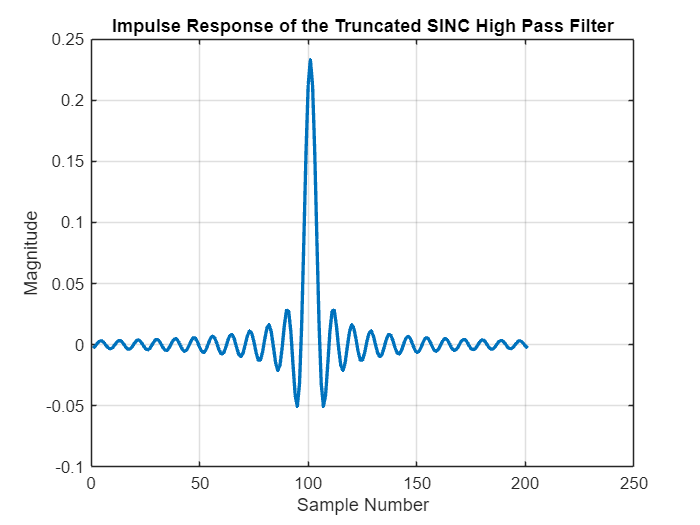

%  Plot the impulse response
figure
plot(truncHPF,'LineWidth',2)
grid on
title('Impulse Response of the Truncated SINC High Pass Filter')
xlabel('Sample Number')
ylabel('Magnitude')

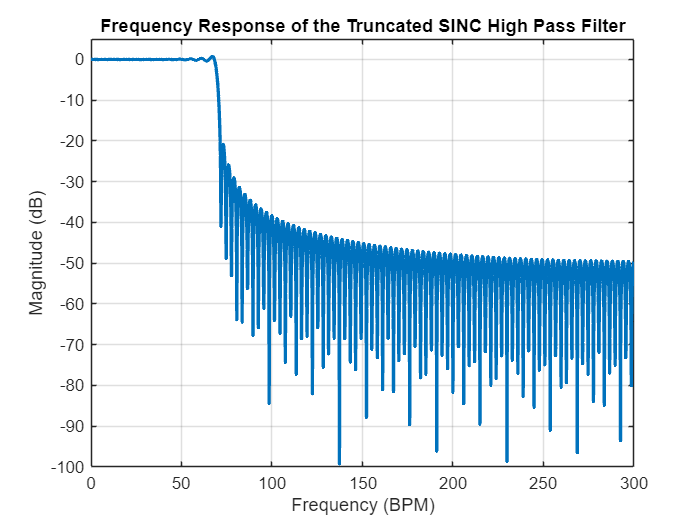


%  Plot the frequency response of the truncated SINC HPF use the
%  freqz function
nSamples = 2048;  %  Use 2048 samples in the frequency response
[fResponseTruncatedSINC, wTruncatedSINC ] = freqz( truncHPF, 1,  nSamples );

figure
plot(wTruncatedSINC/(2*pi)*600, 20*log10(abs(fResponseTruncatedSINC)),'LineWidth',2);
grid on
title('Frequency Response of the Truncated SINC High Pass Filter')
xlabel('Frequency (BPM)')
ylabel('Magnitude (dB)')
xlim([0,300])
ylim([-100,5])

## Questions

#### What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How much attenuation is achieved in the stop band of the filter? 

## Hamming Windowed SINC High Pass Filter

%  Plot the results for the Hamming Windowed SINC High Pass Filter
hamHPF = FIR_Designer( 'nOrder', filterLength, 'cutBPM', freqCornerHPF, 'Window','Hamming', 'PrintHeader',false,'PlotResponses',false);


 Fixed Point scale and FIR Filter Coefficients for easy copy to MATLAB

HFXPT = 4096;

h = [-1, -1, 0, 0, 1, 1, 1, 1, 1, 1, 0, -1, -1, -2,...
-2, -2, -1, 0, 1, 2, 2, 3, 3, 2, 1, 0, -2, -3,...
-4, -5, -4, -3, -1, 1, 4, 6, 7, 7, 6, 3, 0, -4,...
-7, -10, -11, -10, -7, -3, 3, 8, 12, 15, 15, 12, 7, 0,...
-8, -14, -19, -21, -19, -14, -5, 5, 16, 24, 29, 29, 24, 14,...
0, -15, -29, -39, -43, -39, -28, -10, 11, 33, 51, 63, 64, 53,...
31, 0, -36, -72, -100, -115, -110, -84, -33, 38, 127, 224, 323, 412,...
484, 530, 546, 530, 484, 412, 323, 224, 127, 38, -33, -84, -110, -115,...
-100, -72, -36, 0, 31, 53, 64, 63, 51, 33, 11, -10, -28, -39,...
-43, -39, -29, -15, 0, 14, 24, 29, 29, 24, 16, 5, -5, -14,...
-19, -21, -19, -14, -8, 0, 7, 12, 15, 15, 12, 8, 3, -3,...
-7, -10, -11, -10, -7, -4, 0, 3, 6, 7, 7, 6, 4, 1,...
-1, -3, -4, -5, -4, -3, -2, 0, 1, 2, 3, 3, 2, 2,...
1, 0, -1, -2, -2, -2, -1, -1, 0, 1, 1, 1, 1, 1,...
1, 0, 0, -1, -1];


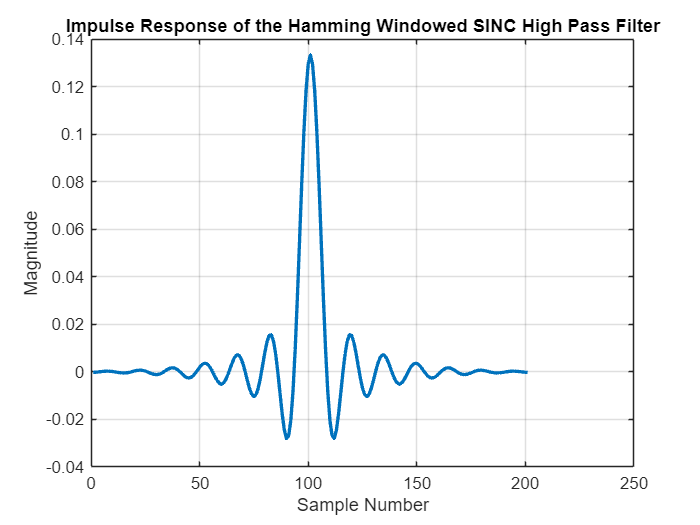


%  Plot the impulse response
figure
plot(hamHPF,'LineWidth',2)
grid on
title('Impulse Response of the Hamming Windowed SINC High Pass Filter')
xlabel('Sample Number')
ylabel('Magnitude')

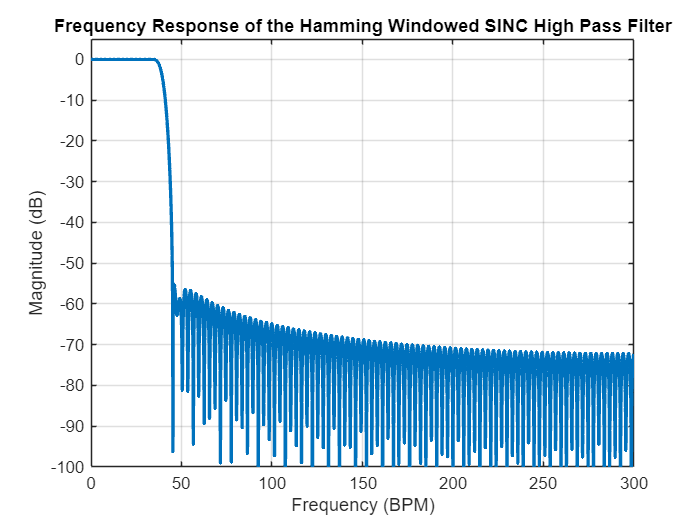


%  Plot the frequency response of the truncated SINC HPF use the
%  freqz function
nSamples = 2048;  %  Use 2048 samples in the frequency response
[fResponseTruncatedSINC, wTruncatedSINC ] = freqz( hamHPF, 1,  nSamples );

figure
plot(wTruncatedSINC/(2*pi)*600, 20*log10(abs(fResponseTruncatedSINC)),'LineWidth',2);
grid on
title('Frequency Response of the Hamming Windowed SINC High Pass Filter')
xlabel('Frequency (BPM)')
ylabel('Magnitude (dB)')
xlim([0,300])
ylim([-100,5])

## Questions

#### What does the pass band look like?  Is it flat? (Zoom in on the pass band to take a closer look).  How does it compare to the truncated SINC filter?  How much attenuation is achieved in the stop band of the filter?  How does it compare to the truncated SINC filter?

# Problem 5 Creating a BandPass Filter 

Combine the Hamming Windowed SINC LPF and the Hamming Windowed SINC HPF impulse responses in a way that they will create a bandpass filter.  Refer to Chapter 14 of Smith and lectures from week 8.  

By placing the lowpass and the highpass filters in series what do you know about the resulting impulse response of the cascaded systems.  How would you calculate the resulting impulse response?

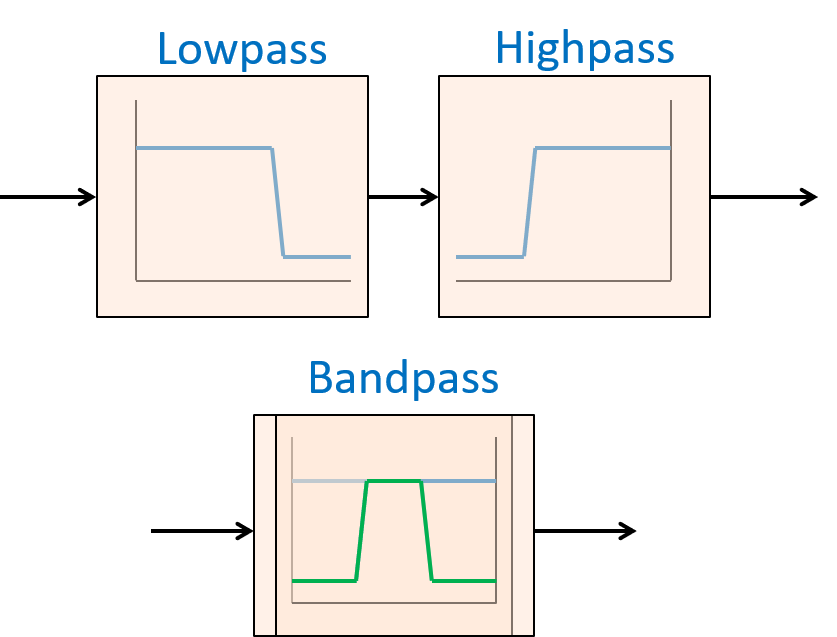

## Bandpass Filter Creation

%  Place your solution to create a bandpass filter from the lowpass and
%  high pass filter impulse responses.
%
%  Plot the impulse response and the frequency response of the bandpass
%  filter

%  Place your solution here


    
    
    %  Plot the frequency response
    
  
